# Inverse Kinematics

Where forward kinematics asks "Given joint angles, where is the end-effector?", inverse kinematics (IK) poses the reverse question: "Given a desired end-effector pose, what joint angles achieve it?" IK is the cornerstone of robotic motion planning and control. Whether programming a manipulator to grasp an object, guiding a humanoid's hand to a switch, or coordinating a mobile manipulator's arm and base, computing valid joint configurations from spatial goals is essential.

If a manipulator's forward-kinematics function 


$$T\left(q\right)=\left\lbrack \begin{array}{ccccc}
 &  &  & | & \\
 & R\left(q\right) &  & | & t\left(q\right)\\
 &  &  & | & \\
-- & -- & -- & + & --\\
0 & 0 & 0 & | & 1
\end{array}\right\rbrack$$


maps joint variables $q\in {\mathbb{R}}^n \;$ to an end-effector pose T, then inverse kinematics seeks one or more solutions q such that


$$T\left(q\right)=T_{\mathrm{desired}} =\left\lbrack \begin{array}{ccccc}
 &  &  & | & \\
 & R_{\mathrm{desired}}  &  & | & t_{\mathrm{desired}} \\
 &  &  & | & \\
-- & -- & -- & + & --\\
0 & 0 & 0 & | & 1
\end{array}\right\rbrack$$


Unlike forward kinematics, the IK problem may have zero, one, or infinitely many solutions, depending on manipulator geometry, reachability, and redundancy.

Some manipulator structures have closed-form solutions, allowing us to analytically compute all solutions to the desired transformation. Universal Robot models all posess the closed form solutions property, making them efficient to work with. 

## Anthropomorphic arm

The Anthropomorphic arm is an example of a strucure with a closed form solution. This configuration is special as it easy to control the position (translation) of the endeffector without considering a specific orientation. The first three Joints of a universal robot form this configuration. 

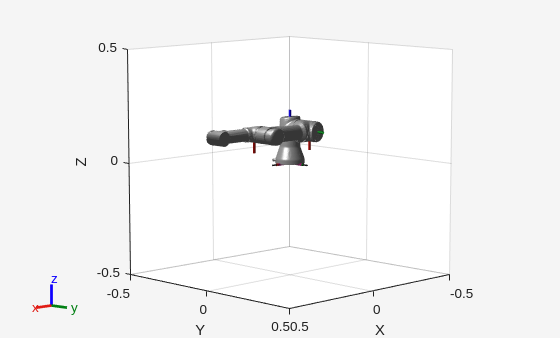

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


anthropomorphic_arm=loadrobot("universalUR3", DataFormat="column");
removeBody(anthropomorphic_arm, "tool0");
removeBody(anthropomorphic_arm, "ee_link");
removeBody(anthropomorphic_arm, "wrist_3_link");
removeBody(anthropomorphic_arm, "wrist_2_link");
removeBody(anthropomorphic_arm, "wrist_1_link");
show(anthropomorphic_arm, zeros(3,1))

For a set of DH parameters a, alpha, d (theta is joint state) we find the homogeneous transformation matrix T03

syms a2 a3 q1 q2 q3 real
DH = [
        0 pi/2  0 q1; 
        a2 0    0 q2; 
        a3 0    0 q3
]; 
A01 = dh2tf(DH(1,:));

$$A01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = dh2tf(DH(2,:));

$$A12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & a_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = dh2tf(DH(3,:));

$$A23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & a_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & a_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A03 = A01 * A12 * A23; 
A03 = simplify(A03)

$$A03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 0 & a_{3}\,\sin\left(q_{2}+q_{3}\right)+a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{3}\,\cos\left(q_{2}+q_{3}\right)+a_{2}\,\cos\left(q_{2}\right) \end{array}$$

For a desired location of the endeffector in the reachable workspace we can solve it using a set of equations. 


$$t_{\mathrm{desired}} =\left\lbrack \begin{array}{c}
x_{\mathrm{desired}} \\
y_{\mathrm{desired}} \\
z_{\mathrm{desired}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \left(q_1 \right)\cdot \left(a_3 \cdot \cos \left(\mathrm{q2}+\mathrm{q3}\right)+a_2 \cdot \cos \left(\mathrm{q2}\right)\right)\\
\sin \left(q_1 \right)\cdot \left(a_3 \cdot \cos \left(\mathrm{q2}+\mathrm{q3}\right)+a_2 \cdot \cos \left(\mathrm{q2}\right)\right)\\
a_3 \cdot \sin \left(q_2 +q_3 \right)+a_2 \cdot \sin \left(q_2 \right)
\end{array}\right\rbrack$$


### 
$$\theta_3$$


using the **geometric equation(???) **we get:


$$\;x_{\mathrm{desired}}^2 +y_{\mathrm{desired}}^2 +z_{\mathrm{desired}}^2 =a_2^2 +a_3^2 +2\cdot \cos \left(q_3 \right)\cdot a_2 \cdot a_3$$


solving for $\cos \left(q_3 \right)$ yields the expression: 


$$\cos \left(q_3 \right)=\frac{x_{\mathrm{desired}}^2 +y_{\mathrm{desired}}^2 +z_{\mathrm{desired}}^2 -a_2^2 -a_3^2 }{\;2\cdot a_2 \cdot a_3 }\;$$


The solution is admissible if $-1\le \cos \left(q_3 \right)\le 1$, which is equivalent to the desired point lying in the reachable workspace. 


$$|a_2 -a_3 |\le \sqrt{x_{\mathrm{desired}}^2 +y_{\mathrm{desired}}^2 +z_{\mathrm{desired}}^2 \;}\le |a_2 +a_3 |$$


where $|a_2 -a_3 |\;$represents the arm being folded onto itself $q_3 =\pi \;$

and $|a_2 +a_3 |$ the arm fully extended $q_3 =0$.

using the property: 

${\sin \left(q_3 \;\right)}^2 +{\cos \left(q_3 \right)}^{2\;} =1$ lets us get two solutions for $\sin \left(\beta \;\right)$ as: 


$$\sin \left(q_3 \right)=\pm \sqrt{\;1-\cos \left(q_3 \;\right)}\;\left\lbrace \begin{array}{ll}
\sin^+ \left(q_3 \right)=+\sqrt{\;1-\cos \left(q_3 \right)} & \\
\sin^- \left(q_3 \right)=-\sqrt{\;1-\cos \left(q_3 \right)} & 
\end{array}\right.$$


this lets us compute $q_3$ as


$$q_3 =\theta_3 =\tan^{-1} \left(\frac{\sin \left(q_3 \right)}{\;\cos \left(q_3 \right)}\right)\left\lbrace \begin{array}{ll}
\theta_{3,1} =\tan^{-1} \left(\frac{\sin^+ \left(q_3 \right)}{\cos \left(q_3 \right)\;}\right)\in \left\lbrack -\pi ,\pi \;\right\rbrack  & \\
\theta_{3,2} =\tan^{-1} \left(\frac{\sin^- \left(q_3 \right)}{\cos \left(q_3 \right)\;}\right)=-\theta {\;}_{3,1}  & 
\end{array}\right.$$


### 
$$\theta_2$$


Looking at the figure we can see that the joint angle q3 defines the reach of the arm. Consider that with a fixed q3 the arms can be modeled as one with a fixed length from the endeffector to the q2 joint. 

using q2 we can now control the resulting z hight of the endeffector 

finally with q1 we can decide the direction of the arm, thinking in polar coordinates theta_1 is the solution to the question where on the circle we want to end up. 

## Symbolic Math Toolbox 

test=simplify(sum(A03(1:3,4).^2,'all'))

$$test = {a_{2}}^{2}+2\,\cos\left(q_{3}\right)\,a_{2}\,a_{3}+{a_{3}}^{2}$$

syms xd yd zd real
c3 = (xd^2+yd^2+zd^2 -a2^2 - a3^2)/(2*a2*a3)

$$c3 = \frac{-{a_{2}}^{2}-{a_{3}}^{2}+{\mathrm{xd}}^{2}+{\mathrm{yd}}^{2}+{\mathrm{zd}}^{2}}{2\,a_{2}\,a_{3}}$$

c3_test = subs(c3, [xd, yd, zd, a2, a3],[2,2,2,1,1])

$$c3\_test = 5$$

## Robotic System Toolbox

### Solver

### generalized Inverse Kinematic

### analytical Inverse Kinematic